# Identification of a Stochastic Rational Spectrum Process from Data 

# Example 2

## Introduction

$1450$ samples of the random variable $y(t)$ of a **stationary stochastic process** were acquired. The aim is to determine the best rational spectrum model, using this data and the **least-squares **approach to **minimising the prediction error**. 

clear
close all
clc

## The Data

Let us load the available data and analyse them 

load identTEST_2.mat

whos

  Name      Size              Bytes  Class     Attributes

  Ts        1x1                   8  double              
  Y_S2      1x1450            11600  double              



As can be seen, there are $N=1450$ samples of the variable $y_{S2}(t)$ and the sampling period $T_s$.

Ndata = numel(Y_S2);
timeVector = Ts .* (0: Ndata-1);

### Removing the average value

Recall that one of the fundamental assumptions of the PEM identification algorithm is that the output sequence of the stationary stochastic process must be zero-mean. Furthermore, the sequence of exogenous inputs, if the process has any inputs at all, must also be zero-mean.

So, let us check if $y(t)$ is a zero mean r.v.

y_av = mean(Y_S2)

y_av = 0.0175

Subtract the average value, to obtain a zero-mean sequence

Y_S2 = Y_S2 - y_av;

### A Preliminary Look to the Data

Let's plot the data and evaluate the sampled autocorrelation function. This preliminary insight is aimed to look at some particular pattern in the  time sequence (i.e. is there a polynomial trend in the data?) and to detect if the stochastic process under study is a simple MA  process or a different stochastic process. 

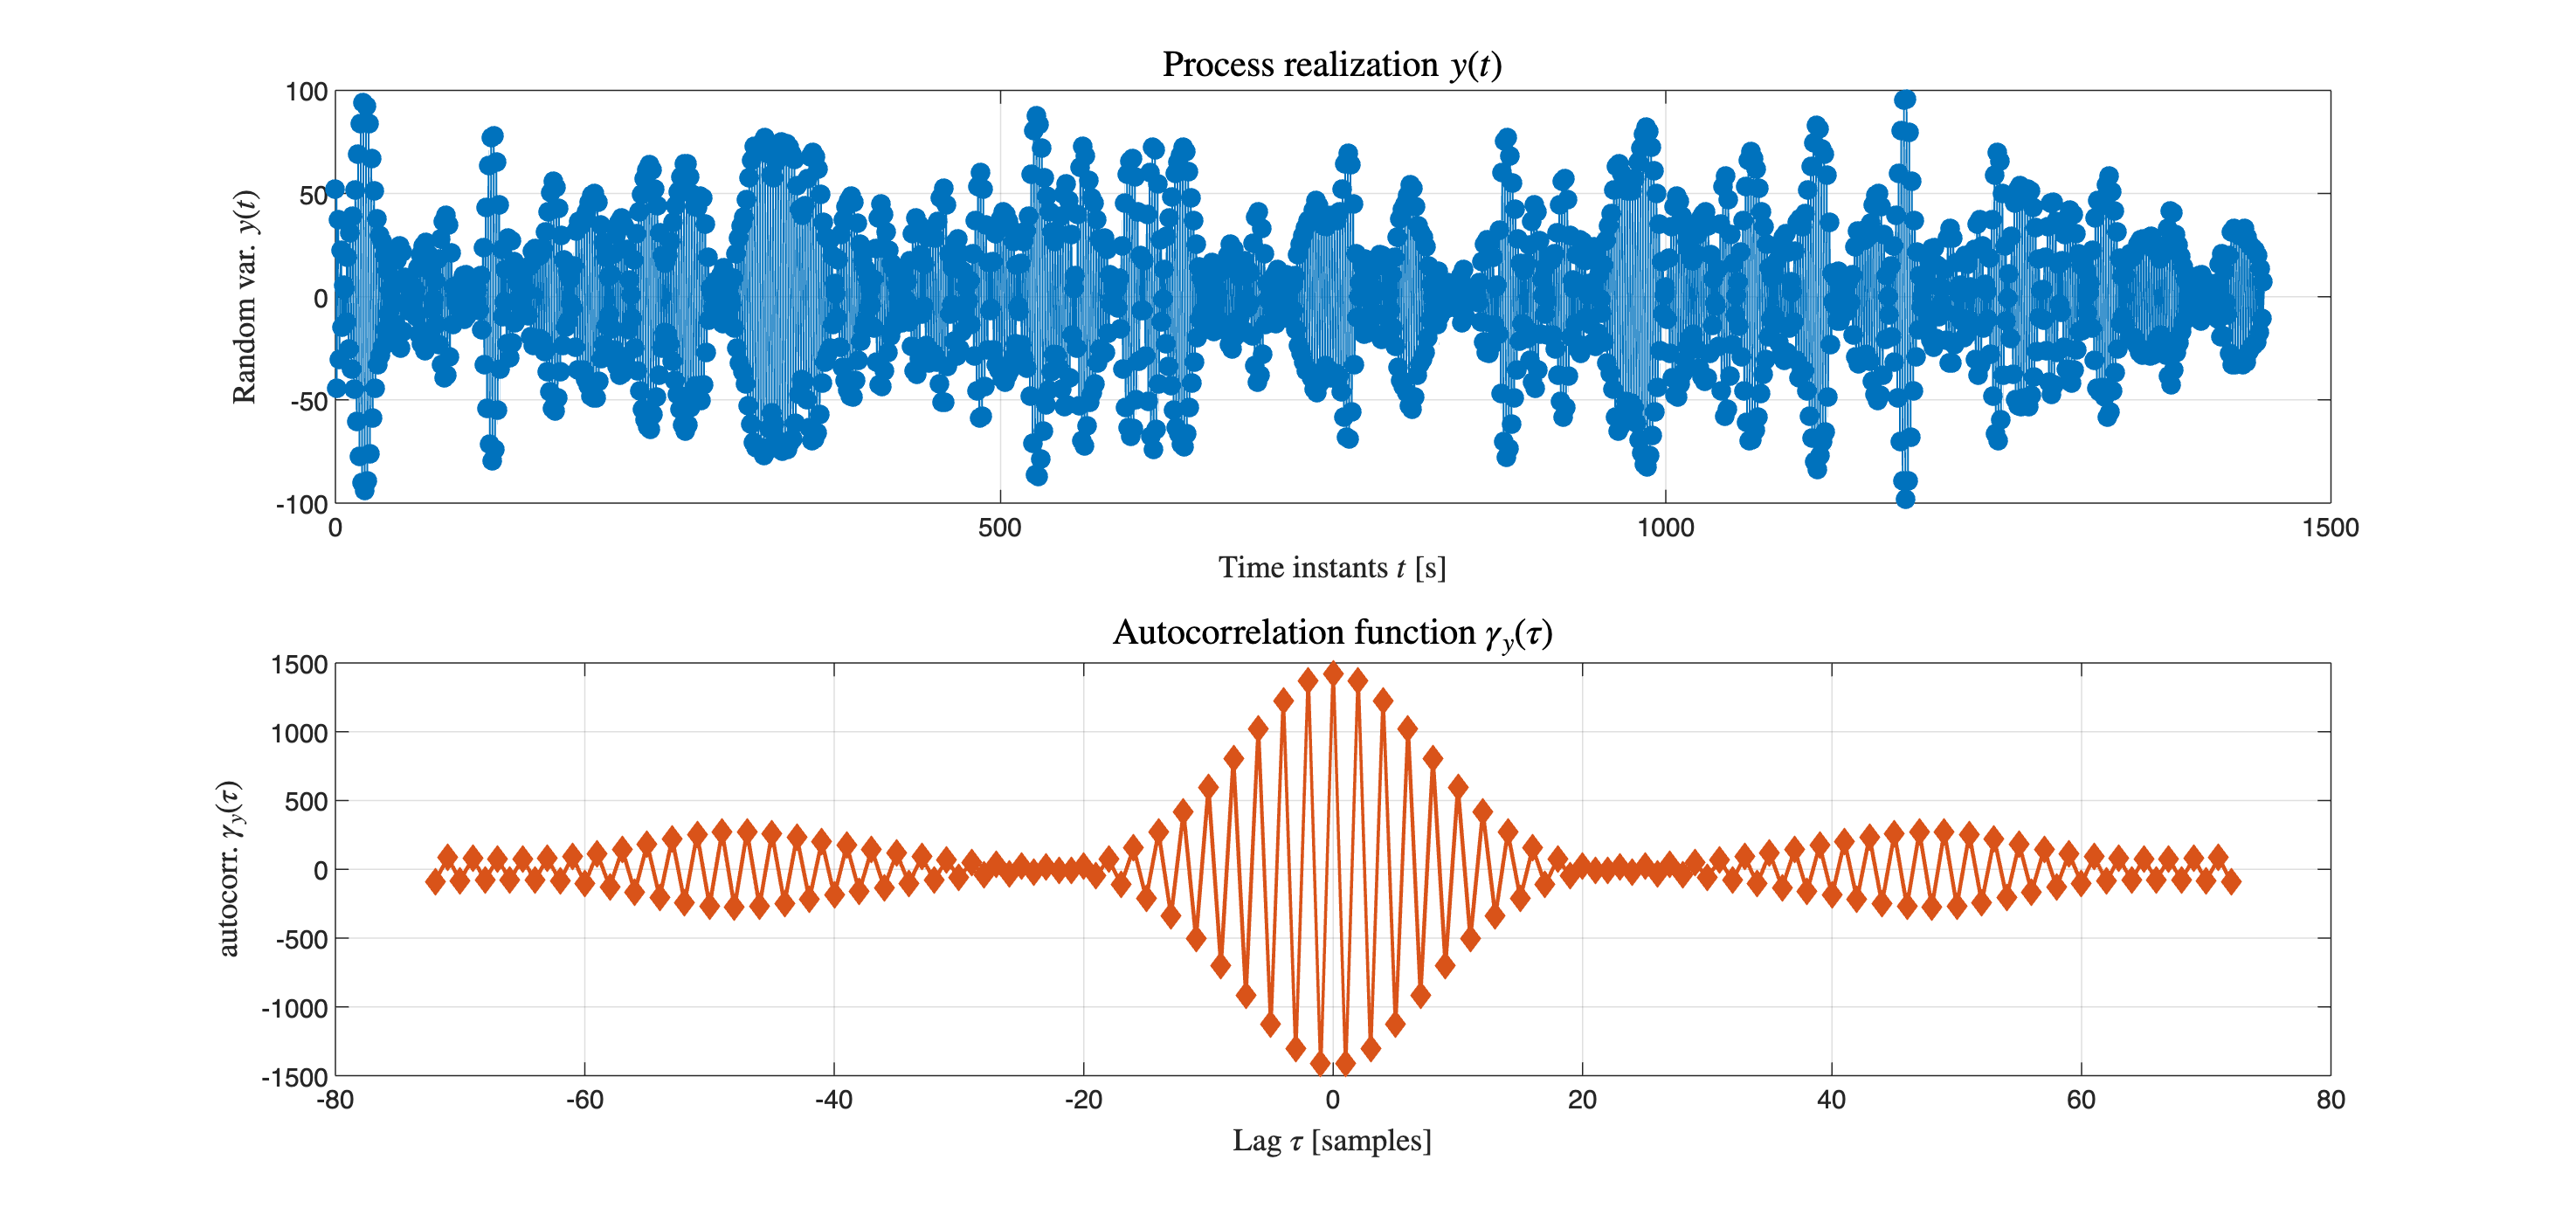

% ---- possible colors ----
FrenchBlue   = [0 0.4470 0.7410];      % French Blue
FlameRed     = [0.8500 0.3250 0.0980]; % Flame Red
Xanthous     = [0.9290 0.6940 0.1250]; % Xanthous
VividViolet  = [0.4940 0.1840 0.5560]; % Vivid Violet
AppleGreen   = [0.4660 0.6740 0.1880]; % Apple Green
BlizzardBlue = [0.3010 0.7450 0.9330]; % Blizzard Blue
VividBurgundy = [0.6350 0.0780 0.1840]; % Vivid Burgundy
% ---- possible colors ----

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);
subplot(2,1,1);
plot(timeVector, Y_S2, "Color", FrenchBlue, "LineStyle","-", "LineWidth", 1.5, ...
    "Marker","o", "MarkerEdgeColor", FrenchBlue, "MarkerFaceColor", FrenchBlue, ...
    "MarkerSize", 6);
grid on
xlabel('Time instants $t$ [s]', 'Interpreter','latex','FontSize',12);
ylabel(' Random var. $y(t)$', 'Interpreter','latex', 'FontSize', 12);
title('Process realization $y(t)$', 'Interpreter','latex','FontSize',14);

subplot(2,1,2);
[gammaVal, tau_lag] = xcorr(Y_S2, floor(Ndata/20), 'unbiased');
plot(tau_lag, gammaVal, 'Color', FlameRed, 'LineStyle','-', 'LineWidth', 1.5, ...
    'Marker','diamond', 'MarkerEdgeColor', FlameRed, 'MarkerFaceColor', FlameRed, ...
    'MarkerSize',6);
grid on
xlabel('Lag $\tau$ [samples]','Interpreter','latex','FontSize',12);
ylabel('autocorr. $\gamma_{y}(\tau)$', 'Interpreter','latex','FontSize',12);
title('Autocorrelation function $\gamma_{y}(\tau)$', 'Interpreter', 'latex', 'FontSize',14)

No polynomial trend is visible in the time domain data. The plot of the autocorrelation function allows us to state that the stochastic process under consideration is not an $MA$ process at all (or at least not an $MA(n)$ with $n \le 72$ ).

## Identification by Minimizing the Prediction Error 

### Searching for the Best AR Model - **Order Determination with FPE, AIC, MDL and CV**

The set of order values $n_A$ to explore, searching for the best $AR(n_A)$ model $\mathcal{M}$:

nA_MAX = 10; % let us analyse the AR(n) models untill n = nA_MAX
nA_SET = (1:nA_MAX);

Let us initialise the data structures used to store the models, the minimum value of the cost function corresponding to each identified model, the results according to the FPE, AIC and MDL indices

ARmodels = cell(nA_MAX, 1);
ARresiduals = cell(nA_MAX, 1);
AR_LossVal = zeros(nA_MAX, 1);
AR_estimVAR = cell(nA_MAX,1);

AR_AndersonWT = zeros(4,1);

ARmodels_CV = cell(nA_MAX, 1);
ARresiduals_CV = cell(nA_MAX, 1);
AR_LossVal_CV = zeros(nA_MAX, 1);


FPEresult = zeros(nA_MAX,1);
AICresult = zeros(nA_MAX,1);
MDLresult = zeros(nA_MAX,1);
CVresult = zeros(nA_MAX,1);


####  Evaluating the Scores

tic
for nA = nA_SET % for each model AR(n) under test
              
    Y_AR = Y_S2;
    % if it is not a row, just transpose it!
    if ~isrow(Y_AR)
        Y_AR = Y_AR';
    end
            
    matPHI = zeros(Ndata-nA, nA); 
    % preallocation of the PHI regressors matrix

    % --- filling the matPHI matrix ---
    for k = nA+1:Ndata
        kk = k-nA;
        matPHI(kk,:) = fliplr(Y_AR(k-nA:k-1));
        % matPHI(t,:) = [y(t-1), y(t-2), ... y(t-nA)]
    end % for k
            
    Y_N = Y_AR(nA+1:end)';   
    % a column vector, without the initial nA values

    % -- identifying the model ---
    hat_theta_N = pinv(matPHI)* Y_N; % alternatively --> matPHI \ Y_N;
    % the minimum of the cost function
    pred_residuals = Y_N - matPHI*hat_theta_N;
    J_loss = mean((pred_residuals).^2) ;
    Smat = matPHI'*matPHI;
     AR_estimVAR{nA} = J_loss .* inv(Smat);

    ARmodels{nA} = hat_theta_N; % storing the model
    AR_LossVal(nA) = J_loss; % storing the loss value
    ARresiduals{nA} = pred_residuals;

    % now let us evaluate the FPE, AIC and MDL indices 
    % for each model using currNdata data
    N = Ndata;
    n = nA;
    FPEresult(n) = ((N+n)/(N-n)) * J_loss;
    AICresult(n) = 2*(n/N) + log(J_loss);
    MDLresult(n) = log(N)*(n/N) + log(J_loss);

    % evaluating the CV score
    Y_Ident = Y_AR(1:ceil(Ndata/2)); % dataset for the CV identificaion task
    Y_Valid = Y_AR(ceil(Ndata/2)+1:end); % dataset for the CV validation task
    currNdataCV = numel(Y_Ident);
    matPHI_CV = zeros(currNdataCV-nA, nA); 
    % preallocation of the PHI regressors matrix

    % --- filling the matPHI matrix ---
    for k = nA+1:currNdataCV
        kk = k-nA;
        matPHI_CV(kk,:) = fliplr(Y_Ident(k-nA:k-1));
        % matPHI(t,:) = [y(t-1), y(t-2), ... y(t-nA)]
    end % for k
            
    Y_N_CV = Y_Ident(nA+1:end)';   
    % a column vector, without the initial nA values

    % -- identifying the model ---
    hat_theta_N_CV = pinv(matPHI_CV)* Y_N_CV; % alternatively --> matPHI_CV \ Y_N_CV;
            
    % --- validating the model ---
    currNdata_V = numel(Y_Valid);
    matPHI_V = zeros(currNdata_V-nA, nA); 
    for k = nA+1:currNdata_V
        kk = k-nA;
        matPHI_V(kk,:) = fliplr(Y_Valid(k-nA:k-1));
        % matPHI(t,:) = [y(t-1), y(t-2), ... y(t-nA)]
    end % for k
    Y_N_V = Y_Valid(nA+1:end)'; 
    pred_residuals_CV = Y_N_V - matPHI_V*hat_theta_N_CV; % <-- NB
    J_loss_CV = mean((pred_residuals_CV).^2) ;

    ARmodels_CV{nA} = hat_theta_N_CV; % storing the model
    ARresiduals_CV{nA} = pred_residuals_CV;
    AR_LossVal_CV(nA) = J_loss_CV; % storing the loss value

    % now let us evaluate the FPE, AIC and MDL indices 
    % for each model using currNdata data
    CVresult(nA) = J_loss_CV;
            
            
end % for nA -- for each model AR(n) under test END

elapsed_t = toc;

fprintf(1, '*** Done! Time spent analysing AR models: %f [s] ***\n\r', elapsed_t);

*** Done! Time spent analysing AR models: 0.085154 [s] ***



#### Analysis of the Scores

[aic_min,aic_id] = min(AICresult);
[fpe_min,fpe_id] = min(FPEresult);
[mdl_min,mdl_id] = min(MDLresult);

[cv_min,cv_id] = min(CVresult);

aic_best_ar = ARmodels{aic_id};aic_best_ar_Name = 'best AR - AIC';
fpe_best_ar = ARmodels{fpe_id};fpe_best_ar_Name = 'best AR - FPE';
mdl_best_ar = ARmodels{mdl_id};mdl_best_ar_Name = 'best AR - MDL';
cv_best_ar = ARmodels_CV{cv_id};cv_best_ar_Name = 'best AR - CV';

best_scores_order = [fpe_id; aic_id; mdl_id; cv_id ];

FPE_N = 1; AIC_N = 2; MDL_N = 3; CV_N = 4;
AR_AndersonWT(FPE_N) = AndersonWhitenessTest(ARresiduals{fpe_id}, 0.05, false);
AR_AndersonWT(AIC_N) = AndersonWhitenessTest(ARresiduals{aic_id}, 0.05, false);
AR_AndersonWT(MDL_N) = AndersonWhitenessTest(ARresiduals{mdl_id}, 0.05, false);
AR_AndersonWT(CV_N) = AndersonWhitenessTest(ARresiduals_CV{cv_id}, 0.05, false);


## The Result

What is the "best model" according to each index?

final_scores = [best_scores_order , AR_AndersonWT ];
RowLabels = cell(4,1);
RowLabels{FPE_N} = fpe_best_ar_Name;
RowLabels{AIC_N} = aic_best_ar_Name;
RowLabels{MDL_N} = mdl_best_ar_Name;
RowLabels{CV_N} = cv_best_ar_Name;

VarNames = {'AR(n) order', 'Whiteness Test'};

array2table(final_scores, "RowNames",RowLabels, "VariableNames", VarNames)

ans = 4×2 table
                     AR(n) order    Whiteness Test
                     ___________    ______________
    best AR - FPE         4               0       
    best AR - AIC         4               0       
    best AR - MDL         4               0       
    best AR - CV          5               0       

Let us evaluate and plot the autocorrelation function of the prediction residuals corresponding to the$AR$ models with order $n=4$ and $n=5$

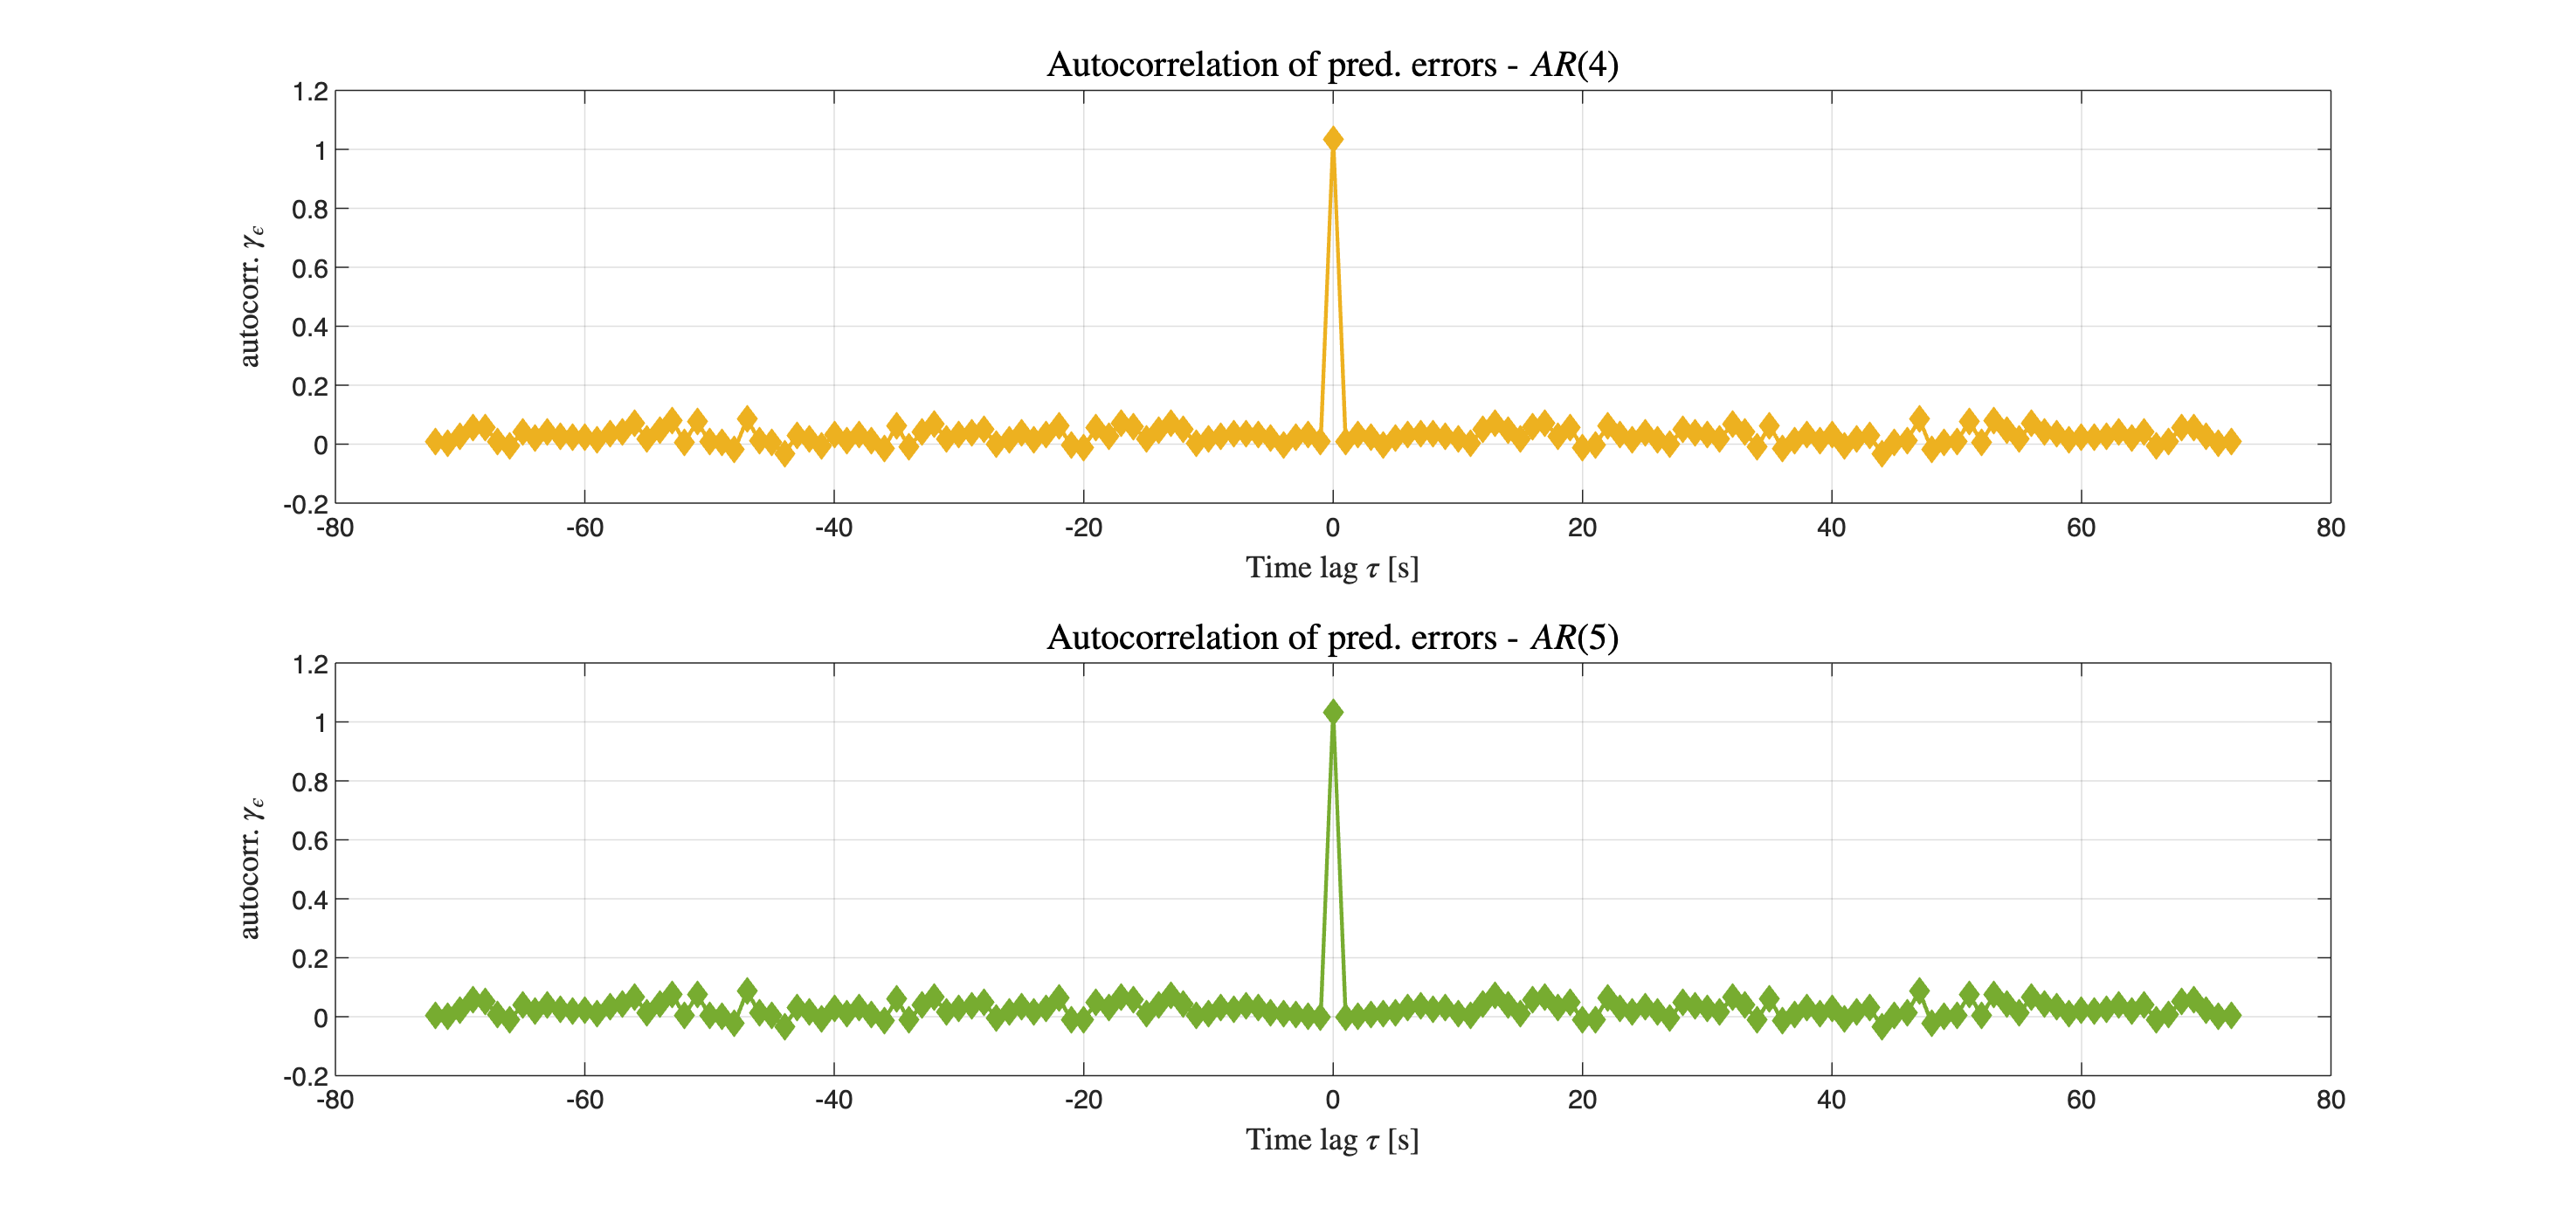

pred_err_AR04 = ARresiduals{4};
pred_err_AR05 = ARresiduals{5};

figure('Units','normalized','Position',[0.1, 0.1, 0.9, 0.75]);
subplot(2,1,1);
[gammaVal, tau_lag] = xcorr(pred_err_AR04, floor(Ndata/20), 'unbiased');
plot(tau_lag, gammaVal, 'Color', Xanthous, 'LineStyle','-', 'LineWidth', 1.5, ...
    'Marker','diamond', 'MarkerEdgeColor', Xanthous, 'MarkerFaceColor', Xanthous, ...
    'MarkerSize',6);
grid on
xlabel('Time lag $\tau$ [s]','Interpreter','latex','FontSize',12);
ylabel('autocorr. $\gamma_{\epsilon}$', 'Interpreter','latex','FontSize',12);
title('Autocorrelation of pred. errors - $AR(4)$', 'Interpreter', 'latex', 'FontSize',14);

subplot(2,1,2);
[gammaVal, tau_lag] = xcorr(pred_err_AR05, floor(Ndata/20), 'unbiased');
plot(tau_lag, gammaVal, 'Color', AppleGreen, 'LineStyle','-', 'LineWidth', 1.5, ...
    'Marker','diamond', 'MarkerEdgeColor', AppleGreen, 'MarkerFaceColor', AppleGreen, ...
    'MarkerSize',6);
grid on
xlabel('Time lag $\tau$ [s]','Interpreter','latex','FontSize',12);
ylabel('autocorr. $\gamma_{\epsilon}$', 'Interpreter','latex','FontSize',12);
title('Autocorrelation of pred. errors - $AR(5)$', 'Interpreter', 'latex', 'FontSize',14);

This time it is not so easy to highlight the differences between the two sample autocorrelation functions.

### Final Remarks

Only the CV-based pre-selected models does not pass the Anderson test. 

The **process** to be identified **for sure is an AR** process of order $n=4$.

Indeed, the "true" parameter vector is


var_xi = 1;  % the white noise variance
mean_xi = 0; % the white noise mean value

Az2 = [1.0000    2.8000    2.8800    1.2800    0.2048];
% the coefficients of the polynomial A(z)
% A(z) <->  1 - a_1 * z^(-1) - a_2 * z^(-2)
%         z^2 - a_1 * z^1    - a_2 * z^ 0

Cz2 = [1,  0]; 
% the coefficients of the polynomial C(z) 
% C(z) <-> 1 +  0 * z^(-1) 
%          1 

Ts = 1; % sampling time 


Thus

theta_o = -Az2(2:end)

theta_o =    -2.8000   -2.8800   -1.2800   -0.2048


whereas the identified $AR(4)$ model is

aic_best_ar'

ans =    -2.7690   -2.7983   -1.2019   -0.1789


Moreover, the estimated white noise variance for the $AR(4)$ model is

% var_xi = 1;  % the white noise variance for the effective process S
hat_WNvar = AR_LossVal(4)

hat_WNvar = 1.0351

and the estimate parameter vector uncertainty is

AR_estimVAR{4}

ans =     0.0007    0.0018    0.0016    0.0005
    0.0018    0.0050    0.0048    0.0016
    0.0016    0.0048    0.0050    0.0018
    0.0005    0.0016    0.0018    0.0007


Using the averaged value of the r.v. $y(t)$, we can estimate the mean value of the stationary white noise process feeding in the process $\mathcal{S}$

hat_Az = [1, -aic_best_ar']; % the estimated coefficients of the polynomial A(z)
hat_Wgain = 1/polyval(hat_Az,1) % the estimated static gain of the filter W(z)

hat_Wgain = 0.1258


% the effective static gain of the filter W(z)
Wgain = 1/polyval(Az2,1)

Wgain = 0.1225


% mean_xi = 0; % the white noise mean value for the effective process S
hat_WN_meanVal = (1/hat_Wgain)*y_av % the estimated white noise mean value

hat_WN_meanVal = 0.1390